BTPollllpllpopopollllo

Student ID: 2021UTM0183

BTP Report

Date : 13 Sept 2024

Ex: 1 :  Compute the steady-state momentum flux $\tau_{yx}$ in $lb_f/ft^2$ when the lower plate velocity V in Fig. 1.1-1 is 1 ft/s in the positive x direction, the plate separation Y is 0.001 ft, and the fluid viscosity $\mu$ is 0.7 cp.


$$\frac{dv_x}{dy} = \tau_{yx}$$


% Ex:1.1-1: Compute steady state momunntum flux
% Given: 
sep = 0.001; % plate separation in ft
vel = 1;     %plate velocity in ft/s
mu =  0.7;    % Viscosity in cp
mu = mu*2.0886*10^(-5); % Viscosity in lbs/ft^2
m_flux = mu*vel/sep;    % dv/dy = V/Y bcz velocity profile is linear
fprintf('The steady-state momentum flux is : %d lb/ft^2 \n', m_flux);

Ex: 2.2-2 : Rework the falling film problem for a position-dependent viscosity $\mu$ = $\mu_0e^{-\alpha x/ \delta}$, which arieses when the film is nonisothermal, as in the condensation of a vapor on a wall. Here $\mu_0
$ is the viscosity at the surface of the film and $\alpha$ is a constant that describes how rapidly $\mu$ decreases as x increases. Such a variation could arise in the flow of a condensate down a wall with a linear temperature gradient through the film.

$-\mu \frac{dv_z}{dx} = \$$\rho$gx cos$\beta$  => f(x)= $ \frac{dv_z}{dx} $ =  $-\frac{\rho \textrm{gx}\cos \beta }{\mu_0 }$$\ e^{\alpha x/ \delta}$                               at x = $\delta$,       $v_z $ = 0     

find $v_z $ at x =0 ?

rho = 0.8*10^3;            % Density (kg/m^3)
g = 9.8;                   % Gravitational acceleration(m/s^2)
beta = 0;                 % Angle(degree)
mu = 0.16;               % viscosity(kg/m.s)
delta = 2.5*10^-3;         % film thickness(m)
alpha = 2;                 % Constant a

c = rho * g * cosd(beta) / mu;           


% Define the function to integrate

The velocity is :6.342553e-01 m/s 


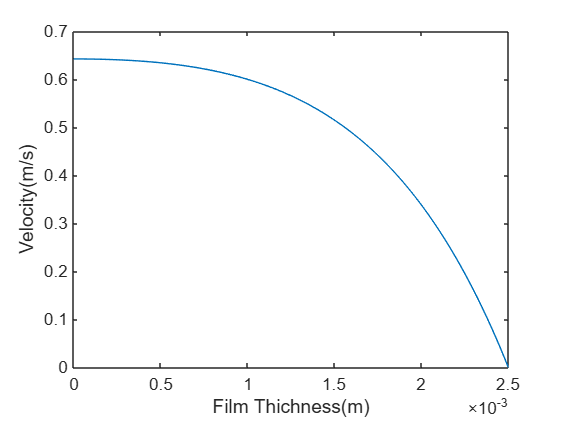

fun = @(x) x .* exp(alpha * x / delta); 
     
% Compute the integral
vel =  -c* integral(fun, delta, 0.5*10^-3);

% velocity
fprintf('The velocity is :%d m/s \n', vel);

% Graph Plot
x_values = linspace(delta, 0, 100);  
v_values = zeros(size(x_values));
for i = 1:length(x_values)

    v_values(i) = -c * integral(fun, delta, x_values(i));
end

figure;
plot(x_values, v_values);
xlabel('Film Thichness(m)');
ylabel('Velocity(m/s)');

Ex: 2.2-2 : Falling film problem for a viscosity $\mu$ 

$-\mu \frac{dv_z}{dx} = \$$\rho$gx cos$\beta$  => f(x)= $ \frac{dv_z}{dx} $ =  $-\frac{\rho \textrm{gx}\cos \beta }{\mu }$ , at x = $\delta$, $v_z $ = 0     

find $v_z $ at x = 0 ?

rho = 0.8*10^3;            % Density (kg/m^3)
g = 9.8;                   % Gravitational acceleration(m/s^2)
beta = 60;                 % Angle(degree)
mu = 0.16;               % viscosity(kg/m.s)
delta = 2.5*10^-3;         % film thickness(m)
%alpha = 2;                 % Constant a

c = rho * g * cosd(beta) / mu;           


% Define the function to integrate
fun = @(x) x; 
     
% Compute the integral
vel =  -c* integral(fun, delta, 0);

The velocity is :7.656250e-02 m/s 


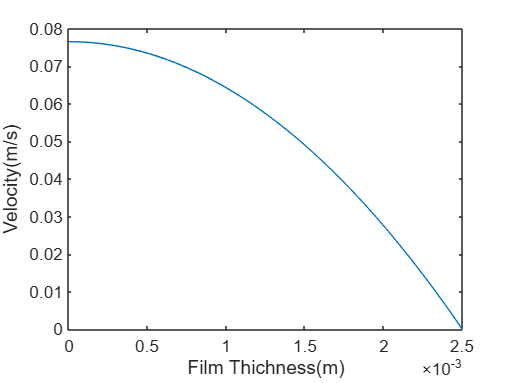


% velocity
fprintf('The velocity is :%d m/s \n', vel);

% Graph Plot
x_values = linspace(delta, 0, 100);  % descretizing thickness
v_values = zeros(size(x_values)); % Empty vector for velocity
for i = 1:length(x_values)
    v_values(i) = -c * integral(fun, delta, x_values(i));
end

figure;

plot(x_values, v_values);
xlabel('Film Thichness(m)');
ylabel('Velocity(m/s)');

Ex: : Falling film problem for a viscosity $\mu$ 

$-\mu \frac{dv_z}{dx} = \$$\rho$gx cos$\beta$  => f(x)= $ \frac{dv_z}{dx} $ =  $-\frac{\rho \textrm{gx}\cos \beta }{\mu }$ , at x = $\delta$, $v_z $ = 0     

find $v_z $ at x = 0 for different values of $\beta$?

## Boundary Conditions:

- $ \frac{dv_z}{dx} $ =0 at x =0 (No shear at the fluid surface)

- $v_z$ =0 at x =δ (No-slip condition at the solid surface)

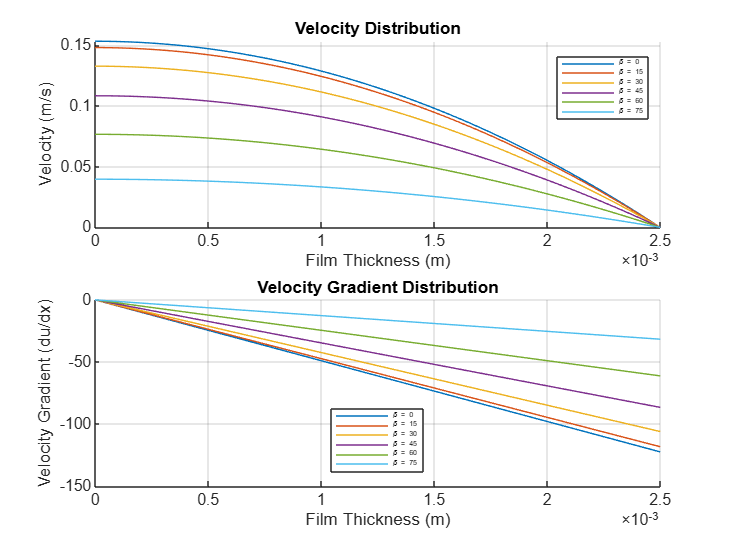

% Constants
rho = 0.8 * 10^3;          % Density (kg/m^3)
g = 9.8;                   % Gravitational acceleration (m/s^2)
delta = 2.5 * 10^-3;       % Film thickness (m)
mu = 0.16;                 % Constant viscosity (Pa.s)
beta_values = [0, 15, 30, 45, 60, 75]; % Beta values

% Prepare the plot
figure;
subplot(2, 1, 1);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity (m/s)');
title('Velocity Distribution');
grid on;

subplot(2, 1, 2);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity Gradient (du/dx)');
title('Velocity Gradient Distribution');
grid on;

% Loop through each beta value
num_samples = length(beta_values);
yMesh = linspace(0, delta, 100);  % Film thickness values

for i = 1:num_samples
    % Extract the current beta value
    beta = beta_values(i);
    
    % Calculate constant c
    c = rho * g * cosd(beta);
    
    % Define the differential equation system with variable viscosity
    % u(1) = u (velocity)
    % u(2) = du/dy (velocity gradient)
    dydx = @(y, u) [u(2); -c / mu];   % [du/dy; d^2u/dy^2]
    
    % Define the boundary conditions
    % ua(2) = du/dy at y=0 -> 0
    % ub(1) = u at y=delta -> 0
    bc = @(ua, ub) [ua(2);  % du/dy = 0 at y=0
                    ub(1)]; % u = 0 at y=delta
    
    % Initial guess for the solution
    uInit = @(y) [0; 0]; % Initial guess for [u; du/dy]
    
    % Solve the boundary value problem
    sol = bvp4c(dydx, bc, bvpinit(yMesh, uInit));
    
    % Extract the solution
    y = sol.x;
    u_values = sol.y(1, :);   % Velocity values
    dudx_values = sol.y(2, :); % Velocity gradient values
    
    % Plot the velocity distribution
    subplot(2, 1, 1);
    plot(y, u_values, 'DisplayName', ['\beta = ', num2str(beta)]);
    
    % Plot the velocity gradient distribution
    subplot(2, 1, 2);
    plot(y, dudx_values, 'DisplayName', ['\beta = ', num2str(beta)]);
end

% Finalize the plots
subplot(2, 1, 1);
legend('show', 'Location', 'best', 'FontSize',4);
hold off;

subplot(2, 1, 2);
legend('show', 'Location', 'best','FontSize',4);
hold off;

Ex: : Falling film problem for a viscosity $\mu$ 

$-\mu \frac{dv_z}{dx} = \$$\rho$gx cos$\beta$  => f(x)= $ \frac{dv_z}{dx} $ =  $-\frac{\rho \textrm{gx}\cos \beta }{\mu }$ , at x = $\delta$, $v_z $ = 0     

find $v_z $ at x = 0 for various viscosity values,  calculated using Jia (2019, pp. 2-3).?

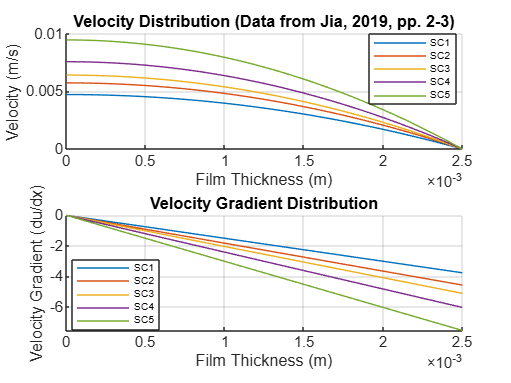

% Read the data from the Excel file
data = readtable("Jia_2019_viscosity_results.xlsx", 'VariableNamingRule', 'preserve');

% Constants
rho = 0.8 * 10^3;          % Density (kg/m^3)
g = 9.8;                   % Gravitational acceleration (m/s^2)
h = 60;                    % Angle (degrees)
delta = 2.5 * 10^-3;       % Film thickness (m)

% Prepare the plot
figure;
subplot(2, 1, 1);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity (m/s)');
title('Velocity Distribution (Data from Jia, 2019, pp. 2-3)');
grid on;

subplot(2, 1, 2);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity Gradient (du/dx)');
title('Velocity Gradient Distribution');
grid on;

% Loop through each sample's viscosity data
num_samples = height(data);
yMesh = linspace(0, delta, 100);  % Film thickness values

for i = 1:num_samples
    % Extract base viscosity and sample name for the current slag
    mu = data.Viscosity(i);           % Base viscosity of the current slag
    sample_name = data.Sample{i};       % Sample name of the current slag (adjust column name if different)
    
    % Calculate constant c
    c = rho * g * cosd(h);
    
    % Define the differential equation system with variable viscosity
    % u(1) = u (velocity)
    % u(2) = du/dy (velocity gradient)
    dydx = @(y, u) [u(2); -c /mu];   % [du/dy; d^2u/dy^2]
    
    % Define the boundary conditions
    % ua(2) = du/dy at y=0 -> 0
    % ub(1) = u at y=delta -> 0
    bc = @(ua, ub) [ua(2);  % du/dy = 0 at y=0
                    ub(1)]; % u = 0 at y=delta
    
    % Initial guess for the solution
    uInit = @(y) [0; 0]; % Initial guess for [u; du/dy]
    
    % Solve the boundary value problem
    sol = bvp4c(dydx, bc, bvpinit(yMesh, uInit));
    
    % Extract the solution
    y = sol.x;
    u_values = sol.y(1, :);   % Velocity values
    dudx_values = sol.y(2, :); % Velocity gradient values
    
    % Plot the velocity distribution
    subplot(2, 1, 1);
    plot(y, u_values, 'DisplayName', sample_name);
    
    % Plot the velocity gradient distribution
    subplot(2, 1, 2);
    plot(y, dudx_values, 'DisplayName', sample_name);
end

% Finalize the plots
subplot(2, 1, 1);
legend('show', 'Location', 'best','FontSize',6);
hold off;

subplot(2, 1, 2);
legend('show', 'Location', 'best','FontSize',6);
hold off;

Ex: : Falling film problem for a viscosity $\mu$ 

$-\mu \frac{dv_z}{dx} = \$$\rho$gx cos$\beta$  => f(x)= $ \frac{dv_z}{dx} $ =  $-\frac{\rho \textrm{gx}\cos \beta }{\mu }$ , at x = $\delta$, $v_z $ = 0     

find $v_z $ at x = 0 for various viscosity values,  calculated using Hurst, 2000, pp. 1-2.?

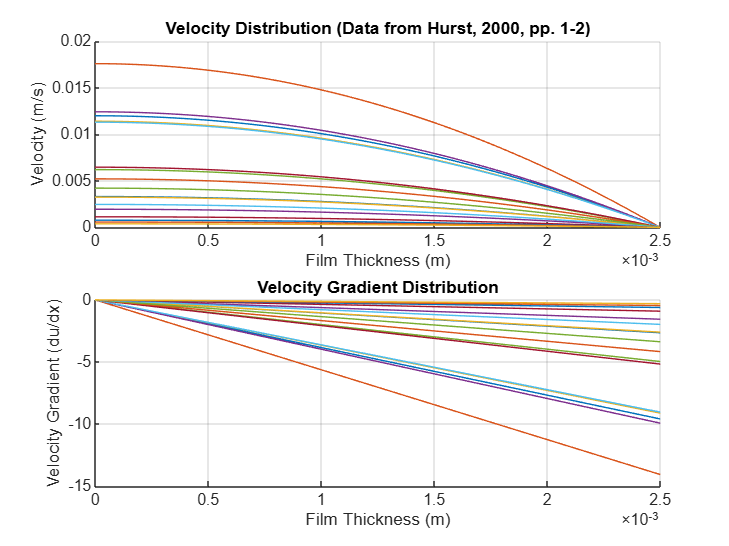

% Read the data from the Excel file
data = readtable("Hurst_2000_viscosity_results.xlsx", 'VariableNamingRule', 'preserve');

% Constants
rho = 0.8 * 10^3;          % Density (kg/m^3)
g = 9.8;                   % Gravitational acceleration (m/s^2)
h = 60;                    % Angle (degrees)
delta = 2.5 * 10^-3;       % Film thickness (m)

% Prepare the plot
figure;
subplot(2, 1, 1);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity (m/s)');
title('Velocity Distribution (Data from Hurst, 2000, pp. 1-2)');
grid on;

subplot(2, 1, 2);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity Gradient (du/dx)');
title('Velocity Gradient Distribution');
grid on;

% Loop through each sample's viscosity data
num_samples = height(data);
yMesh = linspace(0, delta, 100);  % Film thickness values

for i = 1:num_samples
    % Extract base viscosity and sample name for the current slag
    mu = data.Viscosity(i);           % Base viscosity of the current slag
    sample_name = data.Melt{i};       % Sample name of the current slag (adjust column name if different)
    
    % Calculate constant c
    c = rho * g * cosd(h);
    
    % Define the differential equation system with variable viscosity
    % u(1) = u (velocity)
    % u(2) = du/dy (velocity gradient)
    dydx = @(y, u) [u(2); -c /mu];   % [du/dy; d^2u/dy^2]
    
    % Define the boundary conditions
    % ua(2) = du/dy at y=0 -> 0
    % ub(1) = u at y=delta -> 0
    bc = @(ua, ub) [ua(2);  % du/dy = 0 at y=0
                    ub(1)]; % u = 0 at y=delta
    
    % Initial guess for the solution
    uInit = @(y) [0; 0]; % Initial guess for [u; du/dy]
    
    % Solve the boundary value problem
    sol = bvp4c(dydx, bc, bvpinit(yMesh, uInit));
    
    % Extract the solution
    y = sol.x;
    u_values = sol.y(1, :);   % Velocity values
    dudx_values = sol.y(2, :); % Velocity gradient values
    
    % Plot the velocity distribution
    subplot(2, 1, 1);
    plot(y, u_values, 'DisplayName', sample_name);
    
    % Plot the velocity gradient distribution
    subplot(2, 1, 2);
    plot(y, dudx_values, 'DisplayName', sample_name);
end


% Finalize the plots
%subplot(2, 1, 1);
%legend('show', 'Location', 'best','FontSize',3);
%hold off;

%subplot(2, 1, 2);
%legend('show', 'Location', 'best','FontSize',3);
%hold off;


Ex: 2.3-2 Obtain an expression for the mass rate of flow w for an ideal gas in laminar flow in a throughout.long circular tube. The flow is presumed to be isothermal. Assume that the pressure change through the tube is not very large, so that the viscosity can be regarded a constand                

hugen-poiseuille euation for the small length $d_z
$ of the tube     

mass rate flow(w) = $(- \frac{\pi\rho*R^4}{8\mu p_0} )$$(- p\frac{dp}{dz} )$

% given
mu = 0.492;           % viscosity in pa.s
L = 1;                % tube lenght in ft
rho = 78.717;         % fluid density at z=L in lb/ft^3
p = 2.7579*10^5;      % final pressure at z=L in pa
p_0 = 5.51584*10^5;   % inital pressure at z=0 in pa
r = 4.167*10^3;       % tube radius in ft
rho_0 = p_0*rho/p;    % fluid density at z=0 in lb/ft^3
c = -(pi*r^4*rho_0)/(8*mu*p_0*L);

% Define the function to integrate
fun = @(p) p;

% Compute the integral
f_rate =  c* integral(fun,2.7579*10^5 , 5.51584*10^5);

% mass flow rate
fprintf('The mass rate of flow is :%d lb/s  \n', f_rate);



%1. Viscosity Calculation............Arman_2017

% Read input data from Excel
data = readtable("BTP.xlsx",'Sheet', 'Arman_2017','Range', 'A1:K18', 'VariableNamingRule', 'preserve');

% Preallocate output arrays
num_samples = height(data);
mu = zeros(num_samples, 1); % Store calculated viscosity
alpha = zeros(num_samples, 1);    % Store alpha values

              Series                     Sample            Fe3+/Fet_tot    SiO2    Al2O3    CaO     MgO     FeO    Fe2O3    Temperature    Basicity Parameter     Alpha     Viscosity
    __________________________    _____________________    ____________    ____    _____    ____    ____    ___    _____    ___________    __________________    _______    _________

    {'Coal slag'             }    {'Coal Valley (CV)' }        0.56        61.5    13.9     14.2     3.6    2.2     1.4        1500               0.28           0.56657     396.36  
    {'Coal 

b = zeros(num_samples, 1);        % Store parameter b

% Loop through each sample
for i = 1:num_samples
    % Extract mol% composition for the current sample

Results saved to Arman_2017_viscosity_results.xlsx


    SiO2 = data.SiO2(i);
    Al2O3 = data.Al2O3(i);
    CaO = data.CaO(i);
    MgO = data.MgO(i);
    FeO = data.FeO(i);
    Fe2O3 = data.Fe2O3(i);
    Tot_comp = SiO2+Al2O3+CaO+MgO+FeO+Fe2O3;
    T = data.Temperature(i)+273; % Temperature in Kelvin
    %Normalized mol% compositions 
    SiO2=SiO2/Tot_comp ; 
    Al2O3=Al2O3/Tot_comp;
    CaO=CaO/Tot_comp;
    MgO=MgO/Tot_comp;
    FeO=FeO/Tot_comp;
    Fe2O3=Fe2O3/Tot_comp;
    % Calculate x_g, x_m, and x_a
    x_g = SiO2 ;
    x_m = FeO + CaO + MgO;
    x_a = Al2O3 + Fe2O3;

    % Avoid division by zero for alpha calculation
    if (x_m + x_a) == 0
        alpha(i) = NaN; % Mark as invalid if division by zero
        mu(i) = NaN;
        continue; % Skip this sample
    end
    % Calculate alpha (α)
    alpha(i) = x_m / (x_m + x_a);
    % Compute parameter b
    b0 = 13.8 + 39.9355 * alpha(i) - 44.049 * alpha(i)^2;
    b1 = 30.481 - 117.1505 * alpha(i) + 139.9978 * alpha(i)^2;
    b2 = -40.9429 + 234.0486 * alpha(i) - 300.04 * alpha(i)^2;
    b3 = 60.7619 - 153.9276 * alpha(i) + 211.1616 * alpha(i)^2;

    b = b0 + b1 * SiO2 + b2 * SiO2^2 + b3 * SiO2^3;

    % Calculate parameter a (in Pa·s/K)
    a = exp(-0.29 * b - 11.57);

    % Compute viscosity using Weyman equation
    mu(i) = a * T * exp(b*1000/T);
end

% Combine results into a table
result = data;
result.Alpha = alpha;      % Add alpha values
result.Viscosity = mu; % Add viscosity values

% Display results
disp(result);

% Save results to Excel
output_filename = 'Arman_2017_viscosity_results.xlsx';
writetable(result, output_filename);
disp(['Results saved to ', output_filename]);

%1. Viscosity Calculation............Arman_2017

b0 = 114.7671

b1 = 9.0466

b2 = -204.6515

b3 = 41.3345

b = 48.5083

a = 1.8088e-12

b0 = 99.2768

b1 = 7.2964

b2 = -200.0330

b3 = 37.5343

b = 39.5903

a = 1.9971e-11

b0 = 103.8232

b1 = 7.7486

b2 = -201.2641

b3 = 38.5669

b = 49.0041

a = 1.5827e-12

b0 = 159.2085

b1 = 16.6372

b2 = -223.0958

b3 = 55.6945

b = 133.9529

a = 1.8372e-22

b0 = 216.5581

b1 = 30.0763

b2 = -254.2635

b3 = 79.1289

b = 192.9707

a = 2.2999e-29


% Read input data from Excel
data = readtable("BTP.xlsx",'Sheet', 'Arman_2017','Range', 'A1:K18', 'VariableNamingRule', 'preserve');

% Preallocate output arrays
num_samples = height(data);
mu = zeros(num_samples, 1); % Store calculated viscosity
alpha = zeros(num_samples, 1);    % Store alpha values

              Series                     Sample            Fe3+/Fet_tot    SiO2    Al2O3    CaO     MgO     FeO    Fe2O3    Temperature    Basicity Parameter     Alpha     Viscosity 
    __________________________    _____________________    ____________    ____    _____    ____    ____    ___    _____    ___________    __________________    _______    __________

    {'Coal slag'             }    {'Coal Valley (CV)' }        0.56        61.5    13.9     14.2     3.6    2.2     1.4        1500               0.28           0.56657        2444.2
    {'Co

b = zeros(num_samples, 1);        % Store parameter b

% Loop through each sample
for i = 1:5%num_samples
    % Extract mol% composition for the current sample

Results saved to Arman_2017_viscosity_results.xlsx


    SiO2 = data.SiO2(i);
    Al2O3 = data.Al2O3(i);
    CaO = data.CaO(i);
    MgO = data.MgO(i);
    FeO = data.FeO(i);
    Fe2O3 = data.Fe2O3(i);
    Tot_comp = SiO2+Al2O3+CaO+MgO+FeO+Fe2O3;
    T = data.Temperature(i)+273; % Temperature in Kelvin
    %Normalized mol% compositions 
    SiO2=SiO2/Tot_comp ; 
    Al2O3=Al2O3/Tot_comp;
    CaO=CaO/Tot_comp;
    MgO=MgO/Tot_comp;
    FeO=FeO/Tot_comp;
    Fe2O3=Fe2O3/Tot_comp;
    % Calculate x_g, x_m, and x_a
    x_g = SiO2 ;
    x_m = FeO + CaO + MgO;
    x_a = Al2O3 + Fe2O3;

    % Avoid division by zero for alpha calculation
    if (x_m + x_a) == 0
        alpha(i) = NaN % Mark as invalid if division by zero
        mu(i) = NaN;
        continue; % Skip this sample
    end
    % Calculate alpha (α)
    alpha(i) = x_m / (x_m + x_a);
    % Compute parameter b
    b0 = 13.8 + 39.9355 * alpha(i) +244.049 * alpha(i)^2
    b1 = 30.481 - 117.1505 * alpha(i) + 139.9978 * alpha(i)^2
    b2 = -240.9429 + 234.0486 * alpha(i) - 300.04 * alpha(i)^2
    b3 = 60.7619 - 153.9276 * alpha(i) + 211.1616 * alpha(i)^2

    b = b0 + b1 * SiO2 + b2 * SiO2^2 + b3 * SiO2^3

    % Calculate parameter a (in Pa·s/K)
    a = exp(-0.2693 * b - 13.9751)

    % Compute viscosity using Weyman equation
    mu(i) = a * T * exp(b*1000/T);
end

% Combine results into a table
result = data;
result.Alpha = alpha;      % Add alpha values
result.Viscosity = mu; % Add viscosity values

% Display results
disp(result);

% Save results to Excel
output_filename = 'Arman_2017_viscosity_results.xlsx';
writetable(result, output_filename);
disp(['Results saved to ', output_filename]);


%4. Viscosity Calculation............Hurst_2000

% Read input data from Excel
data = readtable("BTP.xlsx",'Sheet', 'Hurst_2000','Range', 'A1:L18', 'VariableNamingRule', 'preserve');

% Preallocate output arrays
num_samples = height(data);
mu = zeros(num_samples, 1); % Store calculated viscosity
alpha = zeros(num_samples, 1);    % Store alpha values
b = zeros(num_samples, 1);        % Store parameter b

% Loop through each sample
for i = 1:num_samples
    A = data.A(i);  %Viscosity Parameter
    B = data.B(i);  %Viscosity Parameter
    R = 8.314  %gas constant in J⋅K−1⋅mol−1
    T_1 = data.T_1(i)+273; % Temperature in Kelvin
    mu(i)= exp(A + B/T_1);    %Viscosity in Pa.s
end

% Combine results into a table
result = data;
result.Viscosity = mu; % Add viscosity values in Pa.s

% Display results
disp(result);

% Save results to Excel
output_filename = 'Hurst_2000_viscosity_results.xlsx';
writetable(result, output_filename);
disp(['Results saved to ', output_filename]);

%5. Viscosity Calculation............Jia_2019

% Read input data from Excel
data = readtable("BTP.xlsx",'Sheet', 'Jia_2019','Range', 'A1:D6', 'VariableNamingRule', 'preserve');

% Preallocate output arrays
num_samples = height(data);
mu = zeros(num_samples, 1); % Store calculated viscosity
alpha = zeros(num_samples, 1);    % Store alpha values
b = zeros(num_samples, 1);        % Store parameter b

% Loop through each sample
for i = 1:num_samples
    ln_A = data.lnA(i);  %Viscosity Parameter
    R = 8.314  %gas constant in J⋅K−1⋅mol−1
    T_1 = data.T_1(i); % Temperature in Kelvin
    E_a = data.E_a(i);
    ln_mu = ln_A + (E_a*1000)/(R*T_1);
    mu(i) = exp(ln_mu);       %Viscosity in Pa.s
end

% Combine results into a table
result = data;
result.Viscosity = mu; % Add viscosity values in Pa.s

% Display results
disp(result);

% Save results to Excel
output_filename = 'Jia_2019_viscosity_results.xlsx';
writetable(result, output_filename);
disp(['Results saved to ', output_filename]);
 o
